cd('/Users/hansem/Dropbox (MIT)/number/codes/NumberEstimation/task/stimuli');

% save line image
size_x=800;
size_y=20; % thinkness

tmp=repmat(plasma(size_x),1,1,size_y); % [800 x 3 x 20]
size(tmp)

ans =    800     3    20


im=shiftdim(tmp,2);
size(im)

ans =     20   800     3


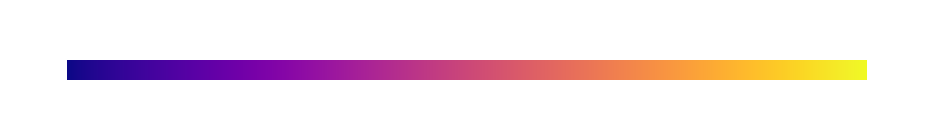


imshow(im)

imwrite(im,'number_line.png','png')

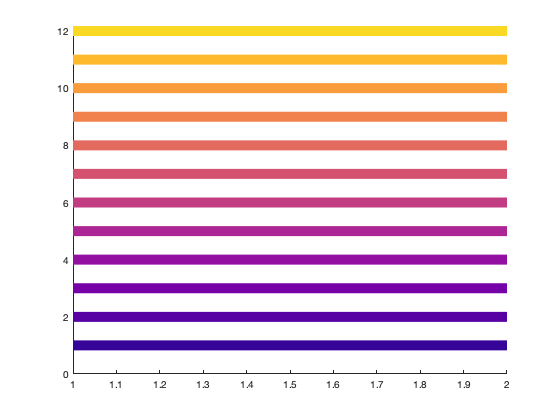

showColor(plasma(12))

a=plasma(12);

minimum=2;
maximum=6;

disp(a(minimum,:))

    0.3410    0.0053    0.6439



disp(a(maximum,:))

    0.7587    0.2343    0.5072



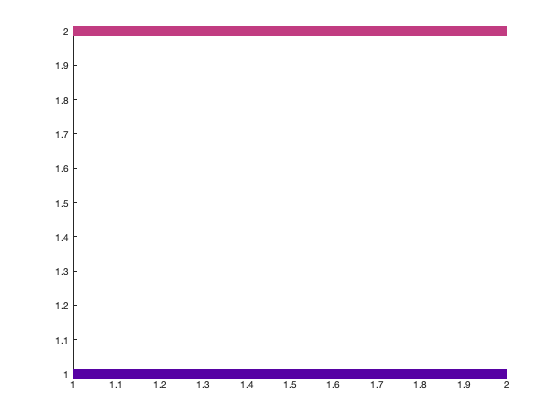




showColor(a([minimum maximum],:))

function showColor(rgb)

% plot colormap
% rgb [m x 3]

%% 
figure; hold all;
for i=1:size(rgb,1)
    plot(1:2,[i i],'linewidth',10,'color',rgb(i,:));
end

end

function [map,num] = plasma(N)
% Perceptually uniform sequential colormap from MatPlotLib.
%
% Copyright (c) 2017-2022 Stephen Cobeldick
%
%%% Syntax:
%  map = plasma
%  map = plasma(N)
%
% Colormap designed by Nathaniel J. Smith and Stefan van der Walt.
%
% For MatPlotLib 2.0 improved colormaps were created in the perceptually
% uniform colorspace CAM02-UCS. The new colormaps are introduced here:
% <http://matplotlib.org/2.0.0rc2/users/dflt_style_changes.html>
% The RGB data is from here: <https://bids.github.io/colormap/>
%
% Note VIRIDIS replaces the awful JET as the MatPlotLib default colormap.
%
%% Examples %%
%
%%% Plot the scheme's RGB values:
% rgbplot(plasma(256))
%
%%% New colors for the COLORMAP example:
% load spine
% image(X)
% colormap(plasma)
%
%%% New colors for the SURF example:
% [X,Y,Z] = peaks(30);
% surfc(X,Y,Z)
% colormap(plasma)
% axis([-3,3,-3,3,-10,5])
%
%% Input and Output Arguments %%
%
%%% Inputs (**=default):
% N = NumericScalar, N>=0, an integer to define the colormap length.
%   = []**, same length as MATLAB's inbuilt colormap functions.
%
%%% Outputs:
% map = NumericMatrix, size Nx3, a colormap of RGB values between 0 and 1.
%
% See also CIVIDIS INFERNO MAGMA TWILIGHT TWILIGHT_SHIFTED VIRIDIS
% TAB10 TAB20 TAB20B TAB20C
% BREWERMAP CUBEHELIX MAXDISTCOLOR PARULA LINES COLORMAP SET
if nargin<1 || isnumeric(N)&&isequal(N,[])
	N = cmDefaultN();
else
	assert(isscalar(N)&&isfinite(N)&&isreal(N),...
		'SC:plasma:N:NotRealFiniteScalarNumeric',...
		'First argument <N> must be a real finite numeric scalar.')
end
%
raw = [0.050383,0.029803,0.527975; 0.063536,0.028426,0.533124; 0.075353,0.027206,0.538007; 0.086222,0.026125,0.542658; 0.096379,0.025165,0.547103; 0.105980,0.024309,0.551368; 0.115124,0.023556,0.555468; 0.123903,0.022878,0.559423; 0.132381,0.022258,0.563250; 0.140603,0.021687,0.566959; 0.148607,0.021154,0.570562; 0.156421,0.020651,0.574065; 0.164070,0.020171,0.577478; 0.171574,0.019706,0.580806; 0.178950,0.019252,0.584054; 0.186213,0.018803,0.587228; 0.193374,0.018354,0.590330; 0.200445,0.017902,0.593364; 0.207435,0.017442,0.596333; 0.214350,0.016973,0.599239; 0.221197,0.016497,0.602083; 0.227983,0.016007,0.604867; 0.234715,0.015502,0.607592; 0.241396,0.014979,0.610259; 0.248032,0.014439,0.612868; 0.254627,0.013882,0.615419; 0.261183,0.013308,0.617911; 0.267703,0.012716,0.620346; 0.274191,0.012109,0.622722; 0.280648,0.011488,0.625038; 0.287076,0.010855,0.627295; 0.293478,0.010213,0.629490; 0.299855,0.009561,0.631624; 0.306210,0.008902,0.633694; 0.312543,0.008239,0.635700; 0.318856,0.007576,0.637640; 0.325150,0.006915,0.639512; 0.331426,0.006261,0.641316; 0.337683,0.005618,0.643049; 0.343925,0.004991,0.644710; 0.350150,0.004382,0.646298; 0.356359,0.003798,0.647810; 0.362553,0.003243,0.649245; 0.368733,0.002724,0.650601; 0.374897,0.002245,0.651876; 0.381047,0.001814,0.653068; 0.387183,0.001434,0.654177; 0.393304,0.001114,0.655199; 0.399411,0.000859,0.656133; 0.405503,0.000678,0.656977; 0.411580,0.000577,0.657730; 0.417642,0.000564,0.658390; 0.423689,0.000646,0.658956; 0.429719,0.000831,0.659425; 0.435734,0.001127,0.659797; 0.441732,0.001540,0.660069; 0.447714,0.002080,0.660240; 0.453677,0.002755,0.660310; 0.459623,0.003574,0.660277; 0.465550,0.004545,0.660139; 0.471457,0.005678,0.659897; 0.477344,0.006980,0.659549; 0.483210,0.008460,0.659095; 0.489055,0.010127,0.658534; 0.494877,0.011990,0.657865; 0.500678,0.014055,0.657088; 0.506454,0.016333,0.656202; 0.512206,0.018833,0.655209; 0.517933,0.021563,0.654109; 0.523633,0.024532,0.652901; 0.529306,0.027747,0.651586; 0.534952,0.031217,0.650165; 0.540570,0.034950,0.648640; 0.546157,0.038954,0.647010; 0.551715,0.043136,0.645277; 0.557243,0.047331,0.643443; 0.562738,0.051545,0.641509; 0.568201,0.055778,0.639477; 0.573632,0.060028,0.637349; 0.579029,0.064296,0.635126; 0.584391,0.068579,0.632812; 0.589719,0.072878,0.630408; 0.595011,0.077190,0.627917; 0.600266,0.081516,0.625342; 0.605485,0.085854,0.622686; 0.610667,0.090204,0.619951; 0.615812,0.094564,0.617140; 0.620919,0.098934,0.614257; 0.625987,0.103312,0.611305; 0.631017,0.107699,0.608287; 0.636008,0.112092,0.605205; 0.640959,0.116492,0.602065; 0.645872,0.120898,0.598867; 0.650746,0.125309,0.595617; 0.655580,0.129725,0.592317; 0.660374,0.134144,0.588971; 0.665129,0.138566,0.585582; 0.669845,0.142992,0.582154; 0.674522,0.147419,0.578688; 0.679160,0.151848,0.575189; 0.683758,0.156278,0.571660; 0.688318,0.160709,0.568103; 0.692840,0.165141,0.564522; 0.697324,0.169573,0.560919; 0.701769,0.174005,0.557296; 0.706178,0.178437,0.553657; 0.710549,0.182868,0.550004; 0.714883,0.187299,0.546338; 0.719181,0.191729,0.542663; 0.723444,0.196158,0.538981; 0.727670,0.200586,0.535293; 0.731862,0.205013,0.531601; 0.736019,0.209439,0.527908; 0.740143,0.213864,0.524216; 0.744232,0.218288,0.520524; 0.748289,0.222711,0.516834; 0.752312,0.227133,0.513149; 0.756304,0.231555,0.509468; 0.760264,0.235976,0.505794; 0.764193,0.240396,0.502126; 0.768090,0.244817,0.498465; 0.771958,0.249237,0.494813; 0.775796,0.253658,0.491171; 0.779604,0.258078,0.487539; 0.783383,0.262500,0.483918; 0.787133,0.266922,0.480307; 0.790855,0.271345,0.476706; 0.794549,0.275770,0.473117; 0.798216,0.280197,0.469538; 0.801855,0.284626,0.465971; 0.805467,0.289057,0.462415; 0.809052,0.293491,0.458870; 0.812612,0.297928,0.455338; 0.816144,0.302368,0.451816; 0.819651,0.306812,0.448306; 0.823132,0.311261,0.444806; 0.826588,0.315714,0.441316; 0.830018,0.320172,0.437836; 0.833422,0.324635,0.434366; 0.836801,0.329105,0.430905; 0.840155,0.333580,0.427455; 0.843484,0.338062,0.424013; 0.846788,0.342551,0.420579; 0.850066,0.347048,0.417153; 0.853319,0.351553,0.413734; 0.856547,0.356066,0.410322; 0.859750,0.360588,0.406917; 0.862927,0.365119,0.403519; 0.866078,0.369660,0.400126; 0.869203,0.374212,0.396738; 0.872303,0.378774,0.393355; 0.875376,0.383347,0.389976; 0.878423,0.387932,0.386600; 0.881443,0.392529,0.383229; 0.884436,0.397139,0.379860; 0.887402,0.401762,0.376494; 0.890340,0.406398,0.373130; 0.893250,0.411048,0.369768; 0.896131,0.415712,0.366407; 0.898984,0.420392,0.363047; 0.901807,0.425087,0.359688; 0.904601,0.429797,0.356329; 0.907365,0.434524,0.352970; 0.910098,0.439268,0.349610; 0.912800,0.444029,0.346251; 0.915471,0.448807,0.342890; 0.918109,0.453603,0.339529; 0.920714,0.458417,0.336166; 0.923287,0.463251,0.332801; 0.925825,0.468103,0.329435; 0.928329,0.472975,0.326067; 0.930798,0.477867,0.322697; 0.933232,0.482780,0.319325; 0.935630,0.487712,0.315952; 0.937990,0.492667,0.312575; 0.940313,0.497642,0.309197; 0.942598,0.502639,0.305816; 0.944844,0.507658,0.302433; 0.947051,0.512699,0.299049; 0.949217,0.517763,0.295662; 0.951344,0.522850,0.292275; 0.953428,0.527960,0.288883; 0.955470,0.533093,0.285490; 0.957469,0.538250,0.282096; 0.959424,0.543431,0.278701; 0.961336,0.548636,0.275305; 0.963203,0.553865,0.271909; 0.965024,0.559118,0.268513; 0.966798,0.564396,0.265118; 0.968526,0.569700,0.261721; 0.970205,0.575028,0.258325; 0.971835,0.580382,0.254931; 0.973416,0.585761,0.251540; 0.974947,0.591165,0.248151; 0.976428,0.596595,0.244767; 0.977856,0.602051,0.241387; 0.979233,0.607532,0.238013; 0.980556,0.613039,0.234646; 0.981826,0.618572,0.231287; 0.983041,0.624131,0.227937; 0.984199,0.629718,0.224595; 0.985301,0.635330,0.221265; 0.986345,0.640969,0.217948; 0.987332,0.646633,0.214648; 0.988260,0.652325,0.211364; 0.989128,0.658043,0.208100; 0.989935,0.663787,0.204859; 0.990681,0.669558,0.201642; 0.991365,0.675355,0.198453; 0.991985,0.681179,0.195295; 0.992541,0.687030,0.192170; 0.993032,0.692907,0.189084; 0.993456,0.698810,0.186041; 0.993814,0.704741,0.183043; 0.994103,0.710698,0.180097; 0.994324,0.716681,0.177208; 0.994474,0.722691,0.174381; 0.994553,0.728728,0.171622; 0.994561,0.734791,0.168938; 0.994495,0.740880,0.166335; 0.994355,0.746995,0.163821; 0.994141,0.753137,0.161404; 0.993851,0.759304,0.159092; 0.993482,0.765499,0.156891; 0.993033,0.771720,0.154808; 0.992505,0.777967,0.152855; 0.991897,0.784239,0.151042; 0.991209,0.790537,0.149377; 0.990439,0.796859,0.147870; 0.989587,0.803205,0.146529; 0.988648,0.809579,0.145357; 0.987621,0.815978,0.144363; 0.986509,0.822401,0.143557; 0.985314,0.828846,0.142945; 0.984031,0.835315,0.142528; 0.982653,0.841812,0.142303; 0.981190,0.848329,0.142279; 0.979644,0.854866,0.142453; 0.977995,0.861432,0.142808; 0.976265,0.868016,0.143351; 0.974443,0.874622,0.144061; 0.972530,0.881250,0.144923; 0.970533,0.887896,0.145919; 0.968443,0.894564,0.147014; 0.966271,0.901249,0.148180; 0.964021,0.907950,0.149370; 0.961681,0.914672,0.150520; 0.959276,0.921407,0.151566; 0.956808,0.928152,0.152409; 0.954287,0.934908,0.152921; 0.951726,0.941671,0.152925; 0.949151,0.948435,0.152178; 0.946602,0.955190,0.150328; 0.944152,0.961916,0.146861; 0.941896,0.968590,0.140956; 0.940015,0.975158,0.131326];
num = size(raw,1);
%
% With small extrapolation when N>num:
vec = linspace(0,num+1,N+2);
map = interp1(1:num,raw,vec(2:N+1),'linear','extrap');
% Interpolation only for all values of N:
%map = interp1(1:num,raw,linspace(1,num,N),'spline')
%
map = max(0,min(1,map));
%
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%plasma
function N = cmDefaultN()
% Get the colormap size from the current figure or default colormap.
try
	F = get(groot,'CurrentFigure');
catch %#ok<CTCH> pre HG2
	N = size(get(gcf,'colormap'),1);
	return
end
if isempty(F)
	N = size(get(groot,'DefaultFigureColormap'),1);
else
	N = size(F.Colormap,1);
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%cmDefaultN